# Lagrangian Approximations for the Stochastic Reachability of a Target Tube

This example will demonstrate how to use the SReachTools toolbox to compute over and under approximations for the stochastic reachability of a target tube via Lagrangian methods.

## Lagrangian Methods

Lagrangian methods perform computations with sets using operations like unions, intersection, Minkowski addition/differences, etc. This computation using set operations can be used to approximate (either over or under) the stochastic reachability of a target tube problem. We will demonstrate that this approach while being be approximative can outperform the current state-of-the-art [dynamic programming](https://doi.org/10.1016/j.automatica.2010.08.006) solution in terms of computation time.

Advantages:

- No gridding, which partially evades the curse of dimensionality

- Provides verification for closed-loop feedback strategies

Disadvantages:

- Using Polyhedral representation, must solve the vertex-facet enumeration problem, limiting computations to ~4 dimensional systems

- Does not provide an explicit control policy, only verifies the existence

The theory for this approach can be found in

- J. D. Gleason, A. P. Vinod, M. M. K. Oishi, "Underapproximation of Reach-Avoid Sets for Discrete-Time Stochastic Systems via Lagrangian Methods," in Proceedings of the IEEE Conference on Decision and Control, 2017. 

- J. D. Gleason, A. P. Vinod, M. M. K. Oishi, "Lagrangian Approximations for Stochastic Reachability of a Target Tube", in preparation.

## Problem Definition

In this example we will look at the viability problem for a double integrator. The system dynamics are:


$$  x_{k+1} = \left[ \begin{array}{cc}
    1 & T \\
    0 & 1
  \end{array}\right] x_{k} + \left[\begin{array}{c}
    \frac{T^{2}}{2} \\
    T
  \end{array}\right] u_{k} + w_{k}$$


where $x_{k+1} \in \mathbf{R}^{2}$ is the state, $u_{k} \in \mathbf{R}$ is the input, and $w_{k} \in \mathbf{R}^{2}$ is the disturbance. The following code defines this system with $w_{k}$ as an i.i.d. Gaussian disturbance with mean $[0, 0]^{\top}$ and variance $\mathrm{diag}(0.01, 0.01)$.

% example parameters
T = 0.25;

% define the system
sys = getChainOfIntegLtiSystem(2, ...
    T, ...
    Polyhedron('lb', -0.1, 'ub', 0.1), ...
     RandomVector('Gaussian', zeros(2,1), 0.001*eye(2)));


## Viability problem as a stochastic reachability of a target tube problem

We examine the viability problem in which we are interested in staying in a set of safe states. In this example the safe set is $\{x \in \mathbf{R}^{2}: |x_{i}| < 1, i = 1, 2\}$. The stochastic reachability of a target tube problem posed as a viability problem by constructing a target tube in which all sets in the tube are the safe set.

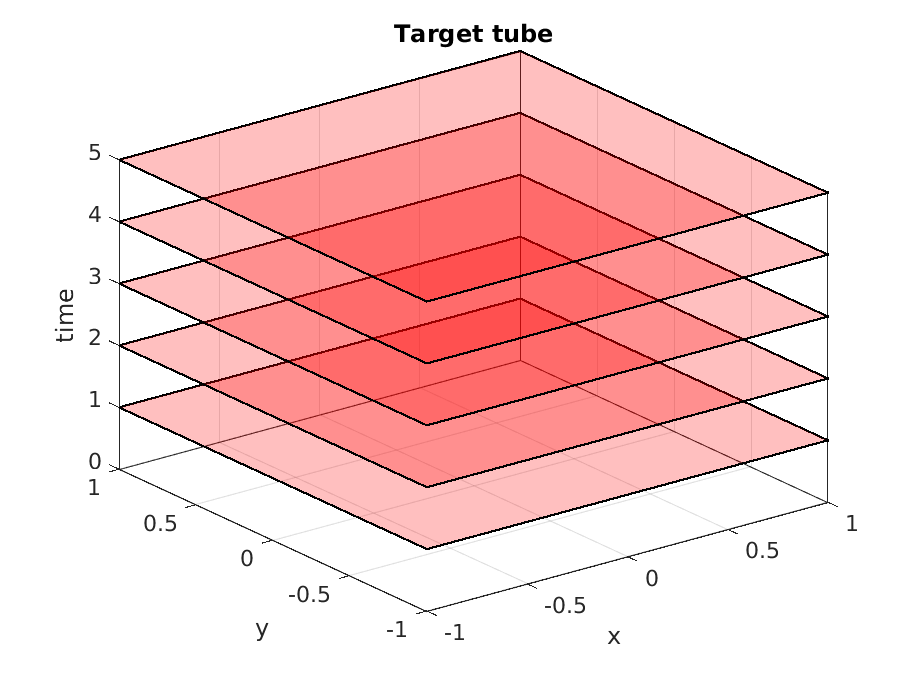

% safe set definition
safe_set = Polyhedron('lb', [-1, -1], 'ub', [1, 1]);
% target tube definition
target_tube = TargetTube('viability', safe_set, 5);
% time_horizon
time_horizon = length(target_tube);
% probability threshold desired
beta = 0.8;
% Plotting of target tube
figure()
hold on    
for time_indx=1:5
    target_tube_at_time_indx = Polyhedron('H',[target_tube(time_indx).A,zeros(size(target_tube(time_indx).A,1),1), target_tube(time_indx).b], 'He',[0 0 1 time_indx]);
    plot(target_tube_at_time_indx, 'alpha',0.25);
    axis([-1 1 -1 1 0 time_indx]);    
end
box on;
grid on;
xlabel('x');
ylabel('y');
zlabel('time');
title('Target tube');

## Lagrangian approximation for stochastic reachability of a target tube

For the Lagrangian methods we compute robust and augmented effective target sets---for the under and overapproximations, respectively. For this computation we need to convert the Gaussian disturbance into a bounded distrubance set which will satisfy the required conditions detailed in the aforementioned papers. We do this here for a an 0.8 probability with the given target tube.

There are several ways to create bounded disturbance sets. Here, we formulate a bounded disturbance by creating a polyhedral approximation of an ellipsoid through random direction choices.

% bounded set for Lagrangian
lag_bounded_set = getBoundedSetForDisturbance(sys.dist, time_horizon, beta, 'random', 50);

Now we can compute the Lagrangian under and overapproximations which we call the robust and augmented effective target sets

robust_eff_target = getRobustEffTarget(sys, target_tube, lag_bounded_set);
aug_eff_target    = getAugEffTarget(sys, target_tube, lag_bounded_set);

Plotting these sets

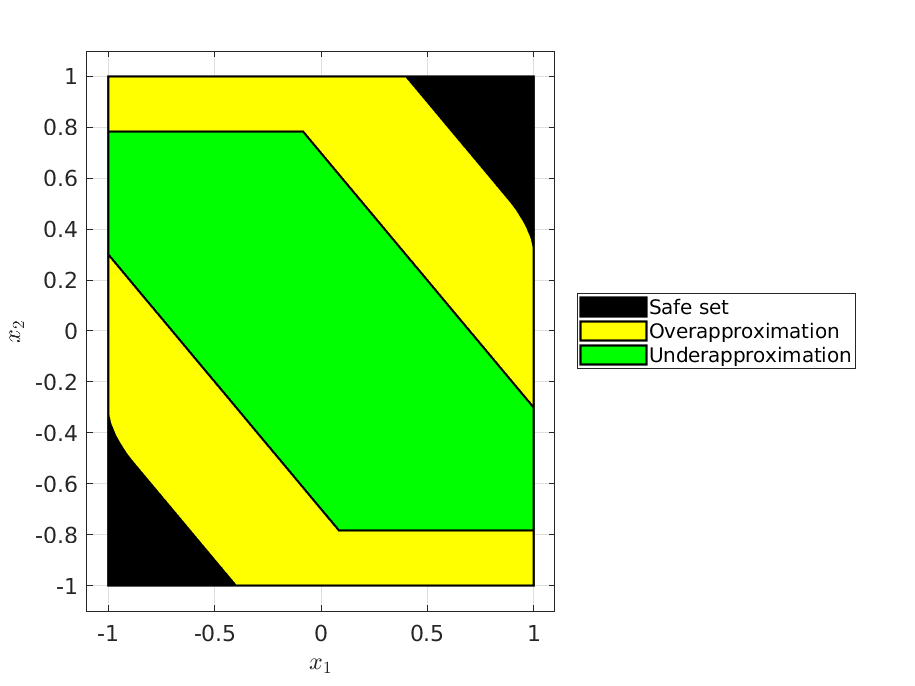

figure();
plot(safe_set, 'color', 'k', 'alpha',1);
hold on;
plot(aug_eff_target, 'color', 'y');
plot(robust_eff_target, 'color', 'g');
hold off;
xlabel('$x_1$', 'Interpreter', 'latex')
ylabel('$x_2$', 'Interpreter', 'latex')
box on;
leg=legend('Safe set','Overapproximation','Underapproximation');
set(leg,'Location','EastOutside');

## A single function to perform of all the above operations: `getApproxStochasticLevelSetViaLagrangian`

The above functions, i.e. computing the bounded set and determining the over and under approximations have been combined into one function for convenience.

tic;
robust_target_2 = getApproxStochasticLevelSetViaLagrangian(sys, ...
    beta, target_tube, 'underapproximation', 'random', 50);
aug_target_2    = getApproxStochasticLevelSetViaLagrangian(sys, ...
    beta, target_tube, 'overapproximation', 'random', 50);
lagrange_time = toc();

Plotting these sets

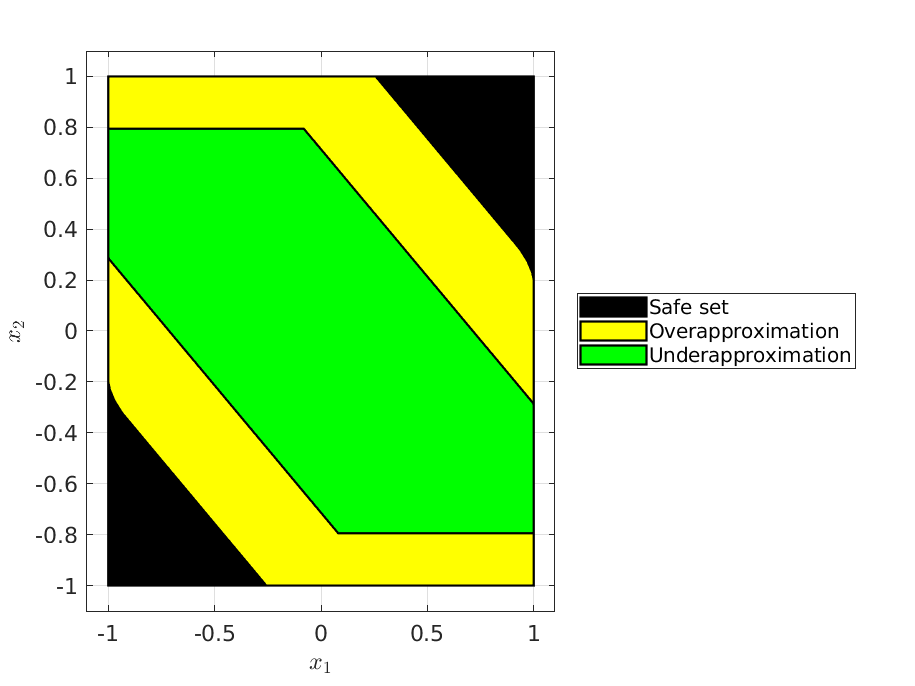

figure();
plot(safe_set, 'color', 'k', 'alpha',1);
hold on;
plot(aug_target_2, 'color', 'y');
plot(robust_target_2, 'color', 'g');
hold off;
xlabel('$x_1$', 'Interpreter', 'latex')
ylabel('$x_2$', 'Interpreter', 'latex')
box on;
leg=legend('Safe set','Overapproximation','Underapproximation');
set(leg,'Location','EastOutside');

Because of the choice or random directions for the ellipse `robust_eff_target` and `robust_target_2` are not exactly equivalent (same for the augmented sets). However they can be seen to be visually near identical.

## Dynamic programming solution

We can compare the results with [dynamic programming](https://doi.org/10.1016/j.automatica.2010.08.006) to see how the approximations appear and how they compare in simulation times. The dynamic programming methods use an 80x80x10 ($x_1\times x_{2} \times u$) grid.

% need to create a state space grid and input space grid
ss_grid = SpaceGrid([-1, -1], [1, 1], 40);
in_grid = InputGrid(-0.1, 0.1, 10);

tic;
grid_probability = getDynProgSolForTargetTube(sys, ...
    ss_grid, in_grid, target_tube);
dynprog_time = toc();

## Simulation times --- Lagrangian approximation is much faster than dynamic programming

The simulation times for Lagrangian computation is much faster than dynamic programming, even when the former computes both an underapproximation and an overapproximation.

lagrange_time

lagrange_time = 1.3139

dynprog_time

dynprog_time = 89.2634

## Plotting all the sets together

As expected, the over-approximation and the under-approximation obtained via Lagrangian approach bounds the dynamic programming solution from "inside" and "outside".

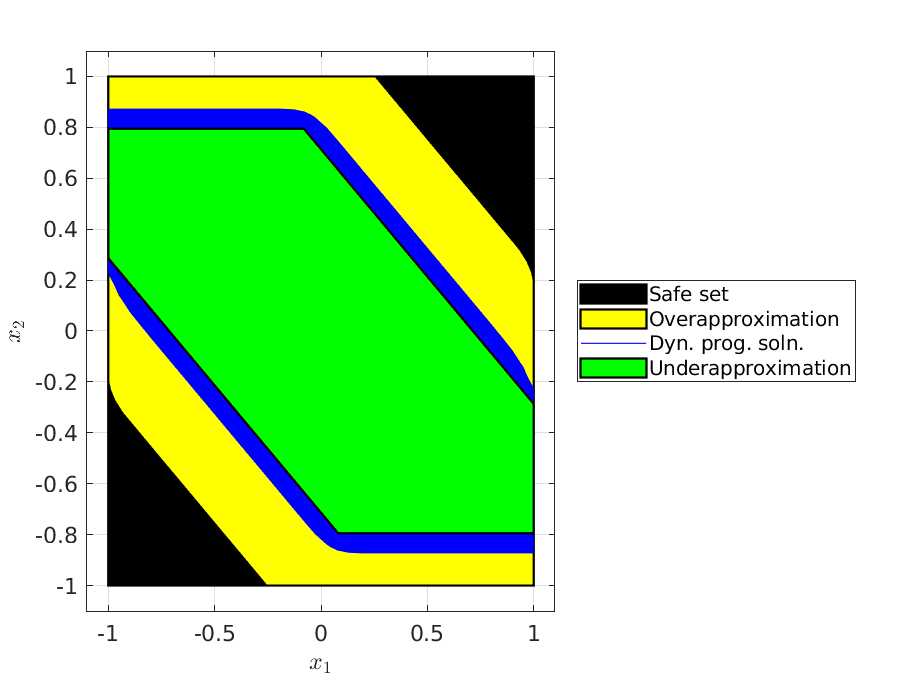

[X,Y] = ss_grid.getMeshGrids();
figure();
plot(safe_set, 'color', 'k', 'alpha',1);
hold on;
plot(aug_target_2, 'color', 'y');
contourf(X,Y,reshape(grid_probability, size(X)), [0.8,0.8], ...
    'color', 'b', 'facecolor', 'b')
plot(robust_target_2, 'color', 'g');
hold off;
xlabel('$x_1$', 'Interpreter', 'latex')
ylabel('$x_2$', 'Interpreter', 'latex')
leg=legend('Safe set','Overapproximation', 'Dyn. prog. soln.','Underapproximation');
set(leg,'Location','EastOutside');
box on;